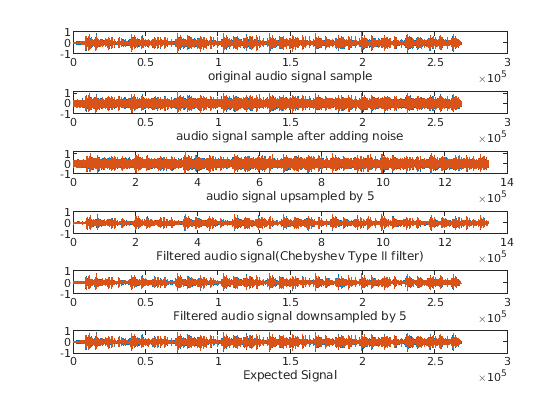

rootdirectory = '/home/lucciffer/college/Notes-classes/sem05/Digital Signal Processing/DSP-assignment/DSP using multirate';
[y,Fs] = audioread(fullfile(rootdirectory,'sampfile.wav'));%Given sample rate,Fs=8000


% code to resample audio
subplot (6,1,1)
plot(y)
xlabel ('original audio signal sample')



%adding noise 
y_noise = y + (1/10)*((randn(size(y))));
subplot (6,1,2)
plot(y_noise)
xlabel ('audio signal sample after adding noise')
soundsc(y_noise,Fs)

pause(35);

%Upsampling by 5
Fs_new1 = 40000;
[Numer, Denom] = rat(Fs_new1/Fs);
y_new1 = resample(y_noise, Numer, Denom);
subplot(6,1,3)
plot(y_new1)
xlabel ('audio signal upsampled by 5')

%filtering
signal = medfilt1(y_new1,90);      % Applying median filter
Fn = Fs/2;                              % Nyquist Frequency (Hz)
Wp = 1000/Fn;                           % Passband Frequency (Normalised)
Ws = 1010/Fn;                           % Stopband Frequency (Normalised)
Rp =   1;                               % Passband Ripple (dB)
Rs = 150;                               % Stopband Ripple (dB)
[n,Ws] = cheb2ord(Wp,Ws,Rp,Rs);         % Filter Order
[z,p,k] = cheby2(n,Rs,Ws,'low');        % Filter Design
[soslp,glp] = zp2sos(z,p,k);    % Convert To Second-Order-Section For Stability
filtered_sound2 = filtfilt(soslp, glp, signal);
subplot(6,1,4);
plot(filtered_sound2);          % Filtered output
xlabel ('Filtered audio signal(Chebyshev Type II filter)');

%Downsampling by 5
Fs_new3 = 8000;
[Numer, Denom] = rat(Fs_new3/40000);
y_new3 = resample(filtered_sound2, Numer, Denom);
subplot(6,1,5)
plot(y_new3)
xlabel ('Filtered audio signal downsampled by 5') 



%expected output
subplot(6,1,6);
plot(y);                  % Expected output
xlabel ('Expected Signal');


soundsc(y,Fs);
pause(35);
soundsc(y_new3,Fs);